# test kinodynamic planning

clear; close all;

### state space

Set up state space world of TWIPR including it's state vector (+ constraints) and input vector (+ constraints). Map state space into configuration space for visualization of the planning results.

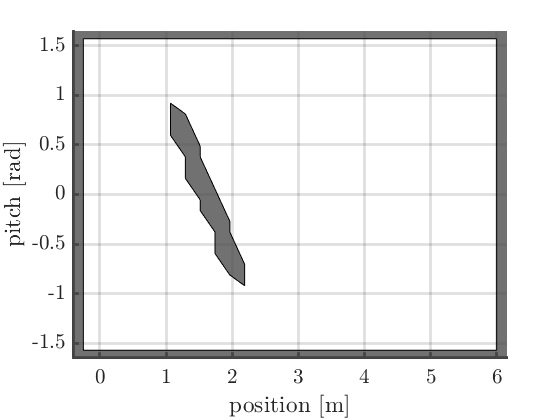

% state space constraints
pitch_max             = deg2rad(90);
pitch_min             = deg2rad(-90);
pitch_velocity_max    = 2*pi;
pitch_velocity_min    = -2*pi;
position_max          = 6;
position_min          = -0.25;
position_velocity_max = 2;
position_velocity_min = -2;
psiD_max              = 210;
psiD_min              = -210;
xmax = [pitch_max; pitch_velocity_max; position_max; position_velocity_max; psiD_max];
xmin = [pitch_min; pitch_velocity_min; position_min; position_velocity_min; psiD_min];
% action space constraints
umax = [2; 3];
umin = [-2; -3];
% handler for state space to config space function
x2y_func = @twipr_x2y;

% set up state space world
statespace = CKinodynamicConfigWorld(xmax, xmin, umax, umin, x2y_func);
% Load our obstacle polygon
load('1_Data/obstacle_0.6m.mat');
% load('1_Data/obstacle_x0.2m_z0.3.mat');
% Add the obstacle to our world
statespace.addObstacle(obstacle_polygon);
% Let's draw the world
figure;
statespace.draw();

### local motion planning

Initialize local motion planning properties.

% Load TWIPR open-loop dynamic model to be used for lmp
chabo_open_loop_model = load("1_Data\chabo_ol_dynamics_disc.mat");
% Function to forward simulate the twipr dynamics to determine state trajectories that result from the planned input trajectories 
% (does not have to use the same model as the Local Motion Planning)
forward_sim_func      = @(x, u)forward_sim(x, u, chabo_open_loop_model.A, chabo_open_loop_model.B); 

% Maximum number of samples per LMP between state nodes
Nmax = 100;
% Setup the local motion planning dynamics matrizes
[ANc,RIc] = lmp_precompute_mimo(Nmax, chabo_open_loop_model.A, chabo_open_loop_model.B); % Can be removed
% LMP function
% lmp_func is a function handle which covers all parameters but xI and xG
% returns input trajectory u between two local goals
lmp_func = @(xI, xG)lmp_time_opt_xcon_precomp_mimo(xI, xG,...
                                              umax, umin,...
                                              psiD_max, psiD_min, ...
                                              Nmax,...
                                              ANc, RIc,...
                                              chabo_open_loop_model);

### motion planning

Elapsed time is 0.948687 seconds.


Ntrial = 400

seed = 8

plan_flag = logical
   1


counter = 1

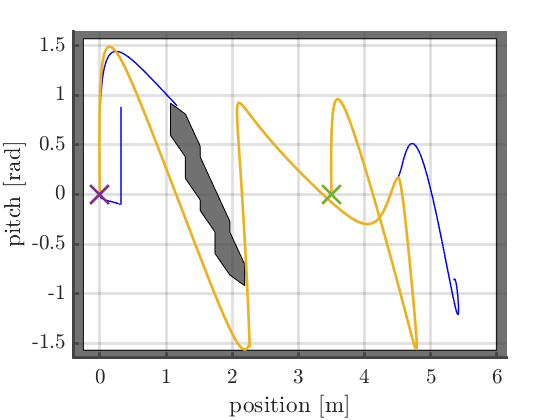

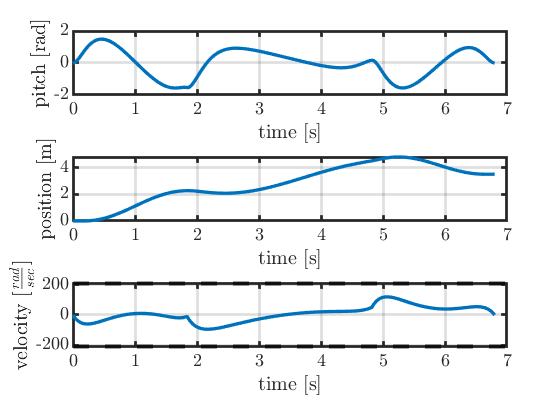

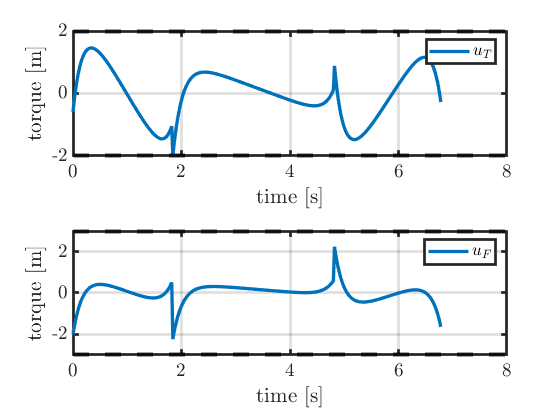

% initial state
xI = [0; 0; 0; 0; 0];     
% Distance function in state space
distance_func = @chabo_state_distance;   % cost function to evaluate "distance" between local goals
% set RNG-Seed
seed = 2;
rng(seed);
% Goal State
xG = [0; 0; 3.5; 0; 0];
% Max number of iterations / nodes
K = 5000;
% Set goal-check-probability
goal_check_probability = 0.95;

nbrOfKLoops     = 4;
nbrOfSeedLoops  = 8;


% tree = cell(nbrOfSeedLoops, 1);
% XP   = cell(nbrOfSeedLoops, 1);
% UP   = cell(nbrOfSeedLoops, 1);
counter = 1;

for k = 4:nbrOfKLoops
    for seed = 8:nbrOfSeedLoops
        Ntrial = Nmax * k;
        % Setup the local motion planning dynamics matrizes
        [ANc,RIc] = lmp_precompute_mimo(Ntrial, chabo_open_loop_model.A, chabo_open_loop_model.B); % Can be removed
        % LMP function
        % lmp_func is a function handle which covers all parameters but xI and xG
        % returns input trajectory u between two local goals
        lmp_func = @(xI, xG)lmp_time_opt_xcon_precomp_mimo(xI, xG,...
                                              umax, umin,...
                                              psiD_max, psiD_min, ...
                                              Ntrial,...
                                              ANc, RIc,...
                                              chabo_open_loop_model);              
        % change RNG-seed
        rng(seed);     
        
        tic;
        [plan_flag, tree{counter}, UP{counter}, XP{counter}, nodelist] = kinodynamic_planning_mimo(statespace, xI, xG, K, lmp_func, forward_sim_func, x2y_func, distance_func, goal_check_probability);
        toc;
        Ntrial
        seed
        plan_flag
        % Plot the results in C-space
        figure;
        statespace.draw();
        tree{counter}.draw('blue');
        if(plan_flag == 0)
            continue;
        end
        
        % plot results of positive kinodynamic planning
        counter
        plotStateTrajectoryInCSpace(XP{counter});
        plotConfiguration(xI([1,3]));
        plotConfiguration(xG([1,3]));
        plotStateTrajectoriesOverTime_mimo(XP{counter}, UP{counter}, umax, umin, psiD_max, psiD_min); 
        drawnow;
        counter = counter  + 1;
        
        if(counter >= 10)
            break;
        end
    end
end

### Post Processing

Post processing to make paths more optimal in terms of dynamic

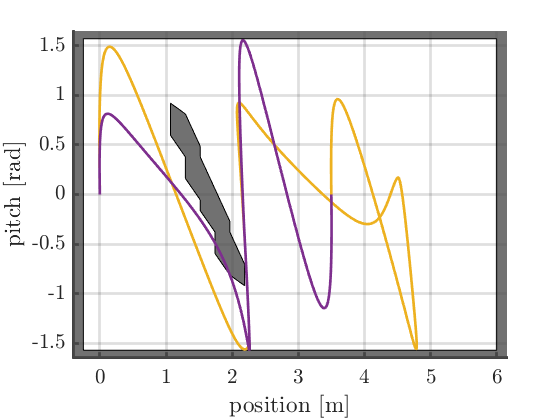

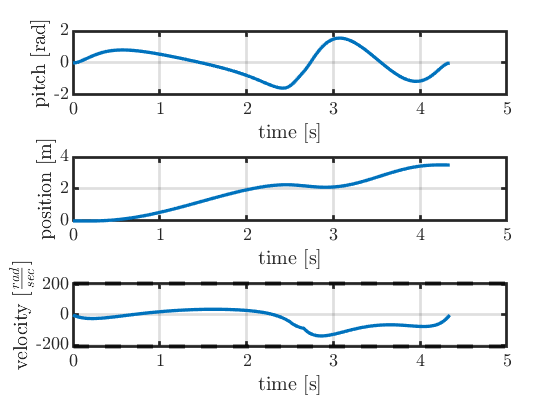

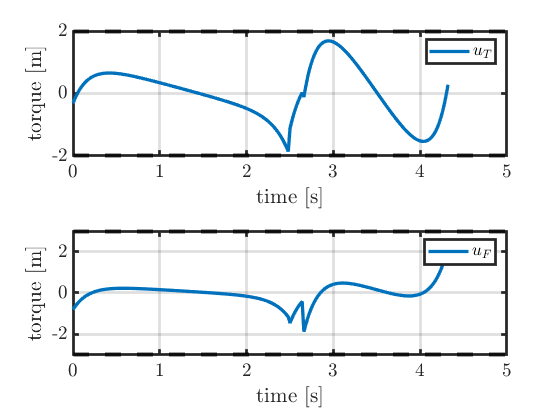

sel = 1;

XPp = XP(sel);
XPp = XPp{1};
UPp = UP(sel);
UPp = UPp{1};

if(XPp~=-1)
    % Let's make the planned trajectory more beautiful
    [Xnew, Unew] = trajectoryPostProcessing_mimo(xI, xG, XPp, UPp, statespace, lmp_func, forward_sim_func);
    figure;
    statespace.draw();
    plotStateTrajectoryInCSpace(XPp);
    plotStateTrajectoryInCSpace(Xnew);
    plotStateTrajectoriesOverTime_mimo(Xnew, Unew, umax, umin, psiD_max, psiD_min);
end

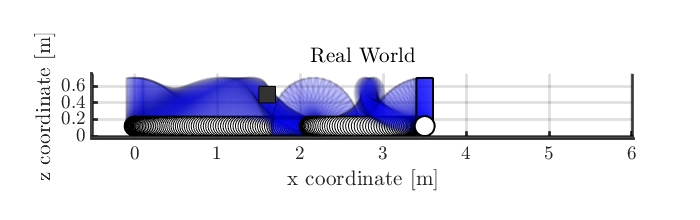

% Let's watch the planned trajectory in the real-world
load('1_Data/real_world.mat');
animate_movement_real_world(real_world, Xnew(1,:),Xnew(3,:));

## save current trajectory

r1 = Xnew(1,:)';
r2 = Xnew(3,:)';

% save('plannedRef_currentSim.mat', 'XPp', 'Xnew', 'r1', 'r2', 'UPp', 'Unew');